# Kreuzkorrelation in MATLAB

Nikolas Grewe

## xcorr(a, b)

Die Kreuzkorrelation ist die wohl wichtigste Funktion in diesem P&S. Mit ihr lässt sich herausfinden, an welchen Stellen sich bekannte Signale in grösseren Sequenzen befinden: Ein mächtiges Werkzeug. In der Praxis werden so insbesondere sogenannte Flags in Signalen gefunden. Das sind Sequenzen, welche z.B. den Anfang oder das Ende einer Nachricht anzeigen. 

Matlab hat bereits eine integrierte Funktion, welche diese Operation durchführt: xcorr(a, b). "a" bezeichnet hier das lange Signal: In diesem suchen wir nach dem kleineren Signal "b". Sie gibt zwei Vektoren zurück: einen "r"-Vektor, der die Werte der Korrelationen beinhaltet, und einen "lags"-Vektor, der die Verschiebungen beinhaltet. Mit dem Formalismus der Formel lässt sich sagen, dass lags die verschiedenen Taus enthält, und dass r die Werte der Integrale bei eben jenen Taus beinhaltet. 


$$\varphi_{\textrm{ab}} \left(\tau \right)=\int_{-\infty }^{\infty } a\left(t\right)\cdot b\left(t-\tau \right)\textrm{dt}$$


Um den Syntax etwas genauer zu verstehen, kann man sich das alles mal in einem Code-Beispiel anschauen:

a = [-1 -1 1 1 1 1 1 -1 1 1];     % Sequenz von Zahlen
b = [1 -1 1];                     % Sequenz, die wir in "a" suchen wollen

[r, lags] = xcorr(a, b);
disp(r);

    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -1.0000   -0.0000    1.0000   -1.0000    1.0000    1.0000    1.0000   -1.0000    3.0000   -1.0000         0    1.0000



disp(lags);

    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9



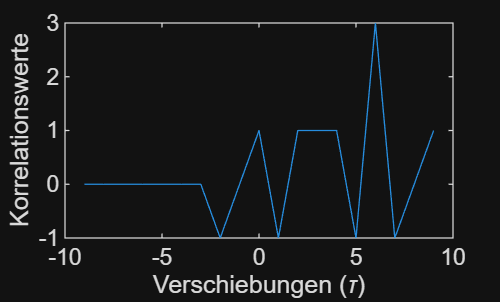


plot(lags, r);
xlabel("Verschiebungen (\tau)");
ylabel("Korrelationswerte");

Auf der x-Achse werden die einzelnen Verschiebungen dargestellt und die entsprechenden Korrelationswerte auf der y-Achse. 

**Wichtiger Punkt!!!**

Auffällig ist, dass "lags" auch negative Werte enthält: Das ist auch völlig normal so. Per Definition werden auch negative Verschiebungen ausgerechnet. In der Signalverarbeitung macht es jedoch wenig Sinn, diese zu beachten: Wir sind wenig daran interessiert, ob ein Signal mal vorkam bevor wir etwas aufgezeichnet haben. Deswegen lässt sich eigentlich immer sagen, dass wir die erste Hälfte von "r" und "lags" wegschmeissen können:

r = r(length(a):end)

r =     1.0000   -1.0000    1.0000    1.0000    1.0000   -1.0000    3.0000   -1.0000         0    1.0000


lags = lags(length(a):end)

lags =      0     1     2     3     4     5     6     7     8     9


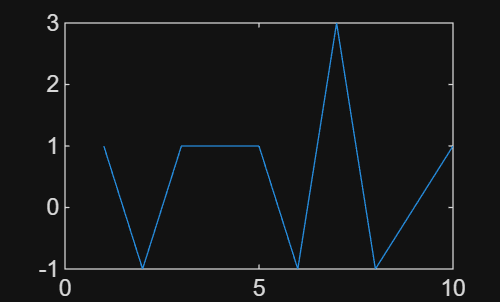


plot(r);

So können wir jetzt auch ganz bequem den Index herausfinden, an dem unsere Sequenz b anfängt!

[max_value, idx] = max(r)

max_value = 3.0000

idx = 7

Wenn man zurück zu den ursprünglichen a und b Vektoren geht, so sieht man sofort, dass die Sequenz [1 -1 1] tatsächlich an der siebten Stelle anfängt. 

Natürlich war dies ein relativ einfaches Beispiel, jedoch funktioniert dieser Workflow eigentlich immer gleich, seien es Kosinus-Signale oder Bits. 

Apropos Bits: Das vorherige Beispiel nutzte ein binäres Signal. Es galt, dass $a_i \in \left\lbrace -1,1\right\rbrace$. Was würde passieren, wenn $a_i \in \left\lbrace 0,1\right\rbrace$?

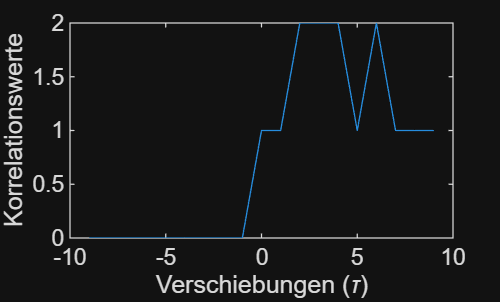

a = [0 0 1 1 1 1 1 0 1 1];  % Gleiche Sequenz wie vorher, jedoch -1 -> 0
b = [1 0 1];                % Ähnlich hier

[r, lags] = xcorr(a, b);

plot(lags, r);
xlabel("Verschiebungen (\tau)");
ylabel("Korrelationswerte");

Ui.

Das was hier mitgenommen werden muss ist, dass eine Kreuzkorrelation mit Werten in {0, 1} eigentlich unbrauchbar ist. Dies ist eine häufige Fehlerquelle. Transformiert also unbedingt, wenn ihr Kreuzkorrelationen mit Bits macht, eure Werte zuerst nach {-1, 1}!